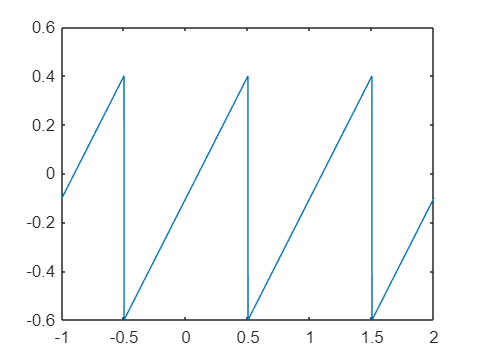

clear variables

T0 = 1; w0 = 2*pi/T0;
Ts = 0.0005; t = -1:Ts:2;
x = t - 0.1 - round(t);
figure;plot(t,x);

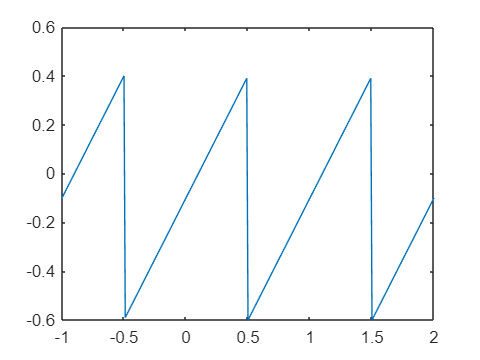

N = 8;
ak = fsAnalysis(x, t, T0, Ts, N);

%Pentru Ts = 0.01:
T0 = 1; w0 = 2*pi/T0;
Ts1 = 0.01; t = -1:Ts1:2;
x1 = t - 0.1 - round(t);
figure; plot(t,x1);

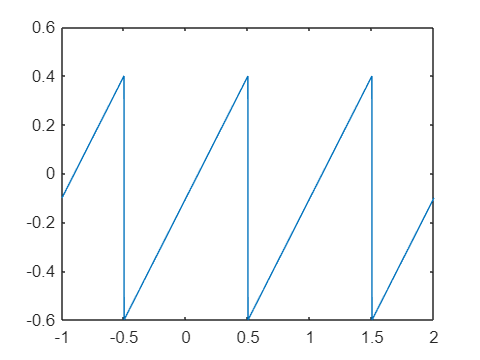

N = 3;
ak = fsAnalysis(x1, t, T0, Ts1, N);

%Pentru Ts = 0.001:
T0 = 1; w0 = 2*pi/T0;
Ts2 = 0.001; t = -1:Ts2:2;
x2 = t - 0.1 - round(t);
figure; plot(t,x2);

N = 10;
ak = fsAnalysis(x2, t, T0, Ts2, N);
a0 = ak(N+1);
ksi0 = 0;
AK = abs(ak(N+2:end));
ksi = angle(ak(N+2:end));

x_est = a0*ones(size(t));
for k = 1:N
x_est = x_est + 2*AK(k)*cos(w0*k*t+ksi(k));
end

figure; plot(t,x,'b',t,x_est,'r');

Error using plot
Vectors must be the same length.

xlabel('t');legend('x(t)','x_{est}(t)');

n0 = 0:N;
figure, subplot(3,1,1);stem(n0,[a0, AK],'.');
legend('Amplitude spectrum')
subplot(3,1,2),stem(n0,[ksi0, ksi],'.g')
legend('Phase spectrum')
subplot(3,1,3),stem(n0,[a0^2, (AK.^2)/2],'r')
label('n'), legend('Power spectrum');
